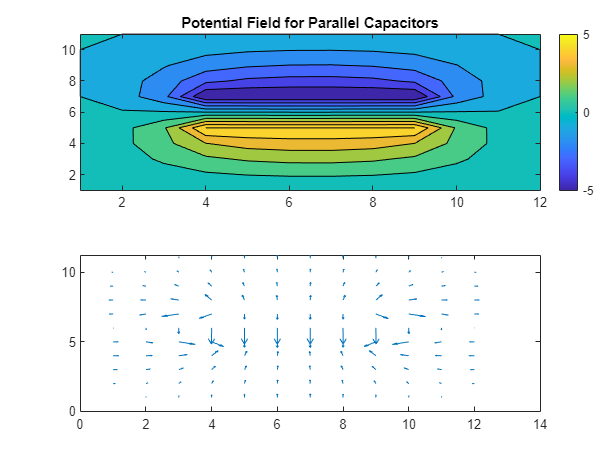

%Question 3
clear all;

%Enter dimensions
Shig = 11; %Space height and width
Swid = 12;
Plen = 5; %Plate length and spacing
Pspac = 1;
Nspac = 1; %Nodal spacing
WAG = 2.5; %Initial guess

%Calculate matrix dimensions
Columns = Swid/Nspac; 
Rows = Shig/Nspac;
PlateNodes = (Plen/Nspac)+1;

%Determine plate placement
Dist = 0;
if rem(PlateNodes,2) == 0
    Dist = (Columns-PlateNodes)/2;
else
    Dist = (Columns-(PlateNodes+1))/2;
end

%Store Error
Terror = 0;
Error = 1;

%Declare matrix and storage matrix
S = zeros(Rows,Columns);
Sold = zeros(Rows,Columns);
S(2:(Rows-1),2:(Columns-1)) = WAG;
S(((Columns/2)-1),((Dist+1):(Dist+PlateNodes))) = 5; %Fix plate values
S(((Columns/2)+1),((Dist+1):(Dist+PlateNodes))) = -5;

%Complete calculation until error is less than 10%
for k = 1:1
    Sold = S; %Iterate matrix values
    for i = 2:(Rows-1)
        for j = 2:(Columns-1)
            if S(i,j) ~= 5 && S(i,j) ~= -5
                S(i,j) = (1/4)*(S(i-1,j)+S(i+1,j)+S(i,j-1)+S(i,j+1));
            else
                ;
            end
        end
    end
    %Calculate error and obtain max for looping
    Terror = abs(S-Sold);
    MaxRow = max(Terror);
    Error = max(MaxRow);
end

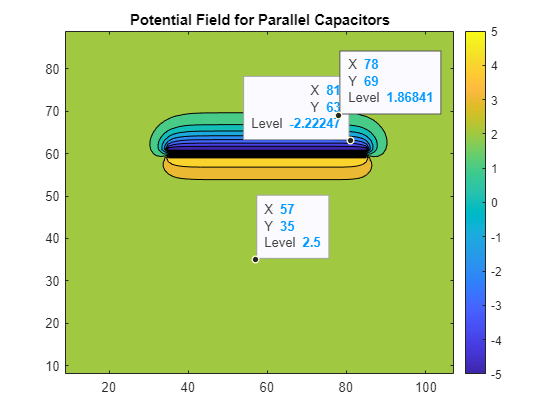

%Question 4
clear all;

%Enter dimensions
Shig = 11; %Space height and width
Swid = 12;
Plen = 5; %Plate length and spacing
Pspac = 1;
Nspac = 0.1; %Nodal spacing
WAG = 2.5; %Initial guess

%Calculate matrix dimensions
Columns = Swid/Nspac; 
Rows = Shig/Nspac;
PlateNodes = (Plen/Nspac)+1;

%Determine plate placement
Dist = 0;
if rem(PlateNodes,2) == 0
    Dist = (Columns-PlateNodes)/2;
else
    Dist = (Columns-(PlateNodes+1))/2;
end

%Store Error
Terror = 0;
Error = 1;

%Declare matrix and storage matrix
S = zeros(Rows,Columns);
Sold = zeros(Rows,Columns);
S(2:(Rows-1),2:(Columns-1)) = WAG;
S(((Columns/2)-1),((Dist+1):(Dist+PlateNodes))) = 5; %Fix plate values
S(((Columns/2)+1),((Dist+1):(Dist+PlateNodes))) = -5;

%Complete calculation until error is less than 10%
while Error > 0.1
    Sold = S; %Iterate matrix values
    for i = 2:(Rows-1)
        for j = 2:(Columns-1)
            if S(i,j) ~= 5 && S(i,j) ~= -5
                S(i,j) = (1/4)*(S(i-1,j)+S(i+1,j)+S(i,j-1)+S(i,j+1));
            else
                ;
            end
        end
    end
    %Calculate error and obtain max for looping
    Terror = abs(S-Sold);
    MaxRow = max(Terror);
    Error = max(MaxRow);
end

%Calculate gradient
[Fx,Fy] = gradient(S);

contourf(S)
title('Potential Field for Parallel Capacitors')
colorbar('eastoutside')

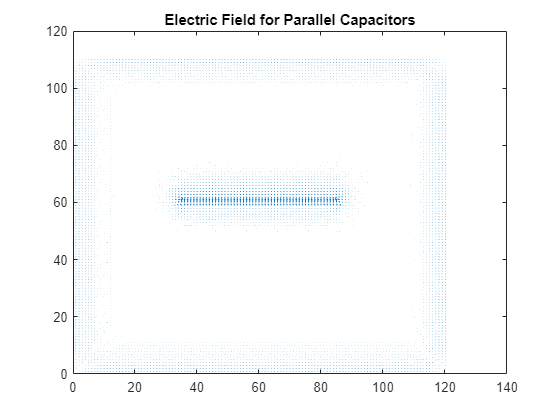

quiver(-Fx,-Fy)
title('Electric Field for Parallel Capacitors')

%Question 5
clear all;

%Enter dimensions
Shig = 11; %Space height and width
Swid = 12;
Plen = 5; %Plate length and spacing
Pspac = 1;
Nspac = 0.25; %Nodal spacing
WAG = 2.5; %Initial guess

%Calculate matrix dimensions
Columns = Swid/Nspac; 
Rows = Shig/Nspac;
PlateNodes = (Plen/Nspac)+1;

%Determine plate placement
Dist = 0;
if rem(PlateNodes,2) == 0
    Dist = (Columns-PlateNodes)/2;
else
    Dist = (Columns-(PlateNodes+1))/2;
end

%Store Error
Terror = 0;
Error = 1;

%Declare matrix and storage matrix
S = zeros(Rows,Columns);
Sold = zeros(Rows,Columns);
S(2:(Rows-1),2:(Columns-1)) = WAG;
S(((Columns/2)-1),((Dist+1):(Dist+PlateNodes))) = 5; %Fix plate values
S(((Columns/2)+1),((Dist+1):(Dist+PlateNodes))) = -5;

%Complete calculation until error is less than 10%
while Error > 0.1
    Sold = S; %Iterate matrix values
    for i = 2:(Rows-1)
        for j = 2:(Columns-1)
            if S(i,j) ~= 5 && S(i,j) ~= -5
                S(i,j) = (1/4)*(S(i-1,j)+S(i+1,j)+S(i,j-1)+S(i,j+1));
            else
                ;
            end
        end
    end
    %Calculate error and obtain max for looping
    Terror = abs(S-Sold);
    MaxRow = max(Terror);
    Error = max(MaxRow);
end

Terror

Terror =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0066    0.0117    0.0151    0.0170    0.0178    0.0178    0.0173    0.0167    0.0161    0.0156    0.0152    0.0150    0.0148    0.0146    0.0146    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0145    0.0146    0.0150    0.0156    0.0166    0.0179    0.0190    0.0194    0.0183    0.0154    0.0110    0.0056         0
         0    0.0117    0.020

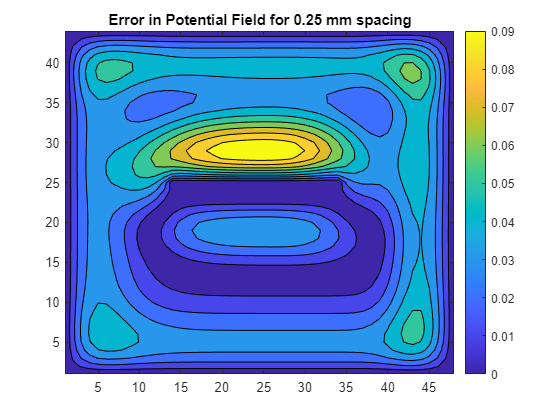

contourf(Terror)
title("Error in Potential Field for 0.25 mm spacing")
colorbar('eastoutside')